# Assignment 2

## 1 How finite should it be?

### 1.1 Like a hot knife through a Butterworth

Construct a bandpass filter which meets the following specifications (normalized frequency): 

- Passband from 0.2 to 0.3. 

- Stopbands from 0 to 0.1 and 0.4 to 1

- Ripples are OK if they don't exceed 2 dB

- The stopband attenuation should be at least -100 dB

clear all; clc;

% Filter specifications
Wp = [0.2 0.3]; % Passband corner frequencies
Ws = [0.1 0.4]; % Stopband corner frequencies
Rp = 2;         % Maximum ripple amplitude
Rs = -100;      % Stopband attenuation

% Butterworth bandpass filter design
[N_bw,Wn_bw] = buttord(Wp,Ws,Rp,-Rs);
[B_bw,A_bw] = butter(N_bw,Wn_bw,"bandpass");

% Chebychev I bandpass filter design
[N_ch1,Wn_ch1] = cheb1ord(Wp,Ws,Rp,-Rs);
[B_ch1,A_ch1] = cheby1(N_ch1,Rp,Wn_ch1,"bandpass");

% Chebychev II bandpass filter design
[N_ch2,Wn_ch2] = cheb1ord(Wp,Ws,Rp,Rs);
[B_ch2,A_ch2] = cheby2(N_ch2,-Rs,Wn_ch2,"bandpass");

% Elliptical bandpass filter design
[N_ep,Wn_ep] = ellipord(Wp,Ws,Rp,-Rs);
[B_ep,A_ep] = ellip(N_ep,Rp,-Rs,Wn_ep,"bandpass");

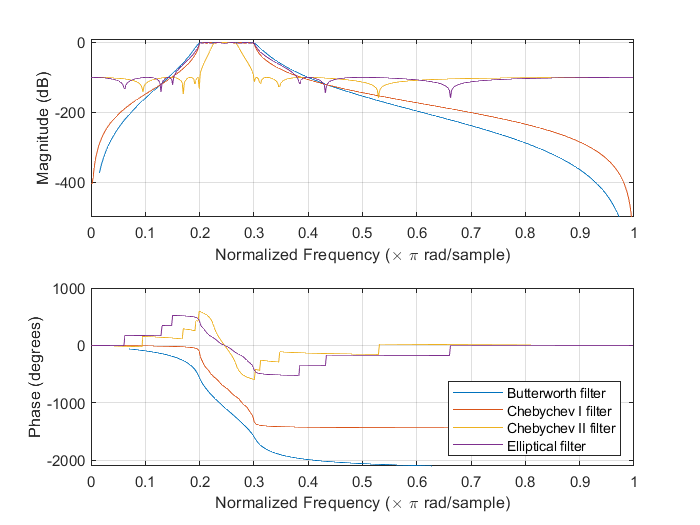

% Frequency responses of four different filters with same specifications
figure("Name", "FR")
subplot(2,1,1)
[H_bw,W] = freqz(B_bw,A_bw);
[H_ch1,~] = freqz(B_ch1,A_ch1);
[H_ch2,~] = freqz(B_ch2,A_ch2);
[H_ep,~] = freqz(B_ep,A_ep);
plot(W/pi,20*log10(abs(H_bw))), hold on;
plot(W/pi,20*log10(abs(H_ch1))), hold on;
plot(W/pi,20*log10(abs(H_ch2))), hold on;
plot(W/pi,20*log10(abs(H_ep))), hold off
grid on
ylim([-500 10])
xlabel("Normalized Frequency (\times \pi rad/sample)")
ylabel("Magnitude (dB)")
subplot(2,1,2)
[phi_bw,~] = phasez(B_bw,A_bw);
[phi_ch1,~] = phasez(B_ch1,A_ch1);
[phi_ch2,~] = phasez(B_ch2,A_ch2);
[phi_ep,~] = phasez(B_ep,A_ep);
plot(W/pi,phi_bw*180/pi), hold on;
plot(W/pi,phi_ch1*180/pi), hold on;
plot(W/pi,phi_ch2*180/pi), hold on;
plot(W/pi,phi_ep*180/pi), hold off
grid on
xlabel("Normalized Frequency (\times \pi rad/sample)")
ylabel("Phase (degrees)")
legend(["Butterworth filter","Chebychev I filter","Chebychev II filter","Elliptical filter"],"Location","southeast")
saveas(gcf,"plots/filter_types_freq_resp","png");

In the following, we choose to pursue the Butterworth filter design, as it provides a flat passband gain with sufficient stopband attenuation. 

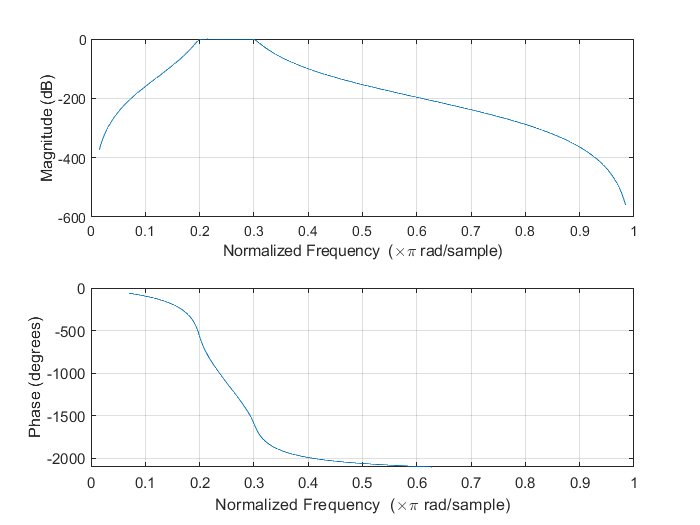

    0.1986    0.3020



% Frequency response
freqz(B_bw,A_bw); disp(Wn_bw)

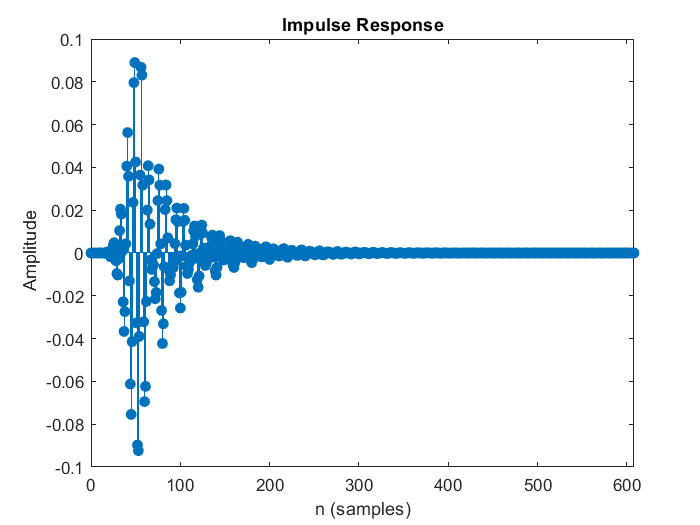

% Impulse response
impz(B_bw,A_bw);

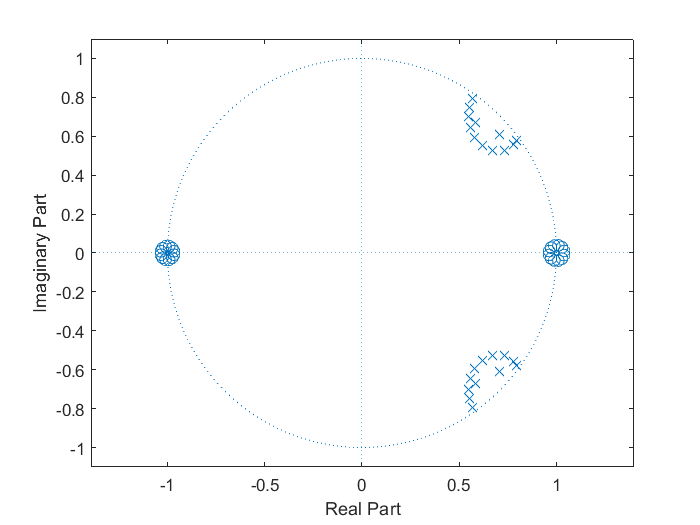

% z-plane plot
zplane(B_bw,A_bw)

Now take the impulse response. Let’s define for practical reasons an effective length of the impulse response the length (in samples) at which the impulse response decays below a value of 10% of its maximum. Now vary the length of the filter:

- Cut the filter at its effective length

- Cut the filter to 75%/60%/40%/10% of its effective length

and compare the frequency response of the resulting filters by plotting them on top of each other. Use a rectangular window and one other window of your choice. Describe what happens to the frequency response when the impulse responses are shortened. 

% Get the impulse response of the Butterworth filter
[h,t] = impz(B_bw,A_bw);

% Find the effective length of the impulse response, where h > 10% of max(H)
el = find(h > 0.1*max(h), 1, "last");

% Cut the filter to 100%/75%/60%/40%/10% of its effective length using a
% rectangular window
h_el_rect   = rectwin(el).*h(1:el);
h_75el_rect = [rectwin(fix(.75*el)).*h(1:fix(.75*el)); zeros(fix(.25*el),1)];
h_60el_rect = [rectwin(fix(.60*el)).*h(1:fix(.60*el)); zeros(fix(.40*el),1)];
h_40el_rect = [rectwin(fix(.40*el)).*h(1:fix(.40*el)); zeros(fix(.60*el),1)];
h_10el_rect = [rectwin(fix(.10*el)).*h(1:fix(.10*el)); zeros(fix(.90*el),1)];

% ... and a Hann window
h_el_hann   = hann(el).*h(1:el);
h_75el_hann = [hann(fix(.75*el)).*h(1:fix(.75*el)); zeros(fix(.25*el),1)];
h_60el_hann = [hann(fix(.60*el)).*h(1:fix(.60*el)); zeros(fix(.40*el),1)];
h_40el_hann = [hann(fix(.40*el)).*h(1:fix(.40*el)); zeros(fix(.60*el),1)];
h_10el_hann = [hann(fix(.10*el)).*h(1:fix(.10*el)); zeros(fix(.90*el),1)];

% Fourier transform the impulse response to get the filters' frequency response
H_el_rect   = fft(h_el_rect); H_el_rect = H_el_rect(1:ceil(length(h_el_rect)/2));
H_75el_rect = fft(h_75el_rect); H_75el_rect = H_75el_rect(1:ceil(length(H_75el_rect)/2));
H_60el_rect = fft(h_60el_rect); H_60el_rect = H_60el_rect(1:ceil(length(H_60el_rect)/2));
H_40el_rect = fft(h_40el_rect); H_40el_rect = H_40el_rect(1:ceil(length(H_40el_rect)/2));
H_10el_rect = fft(h_10el_rect); H_10el_rect = H_10el_rect(1:ceil(length(H_10el_rect)/2));
H_el_hann   = fft(h_el_hann); H_el_hann = H_el_hann(1:ceil(length(h_el_hann)/2));
H_75el_hann = fft(h_75el_hann); H_75el_hann = H_75el_hann(1:ceil(length(H_75el_hann)/2));
H_60el_hann = fft(h_60el_hann); H_60el_hann = H_60el_hann(1:ceil(length(H_60el_hann)/2));
H_40el_hann = fft(h_40el_hann); H_40el_hann = H_40el_hann(1:ceil(length(H_40el_hann)/2));
H_10el_hann = fft(h_10el_hann); H_10el_hann = H_10el_hann(1:ceil(length(H_10el_hann)/2));

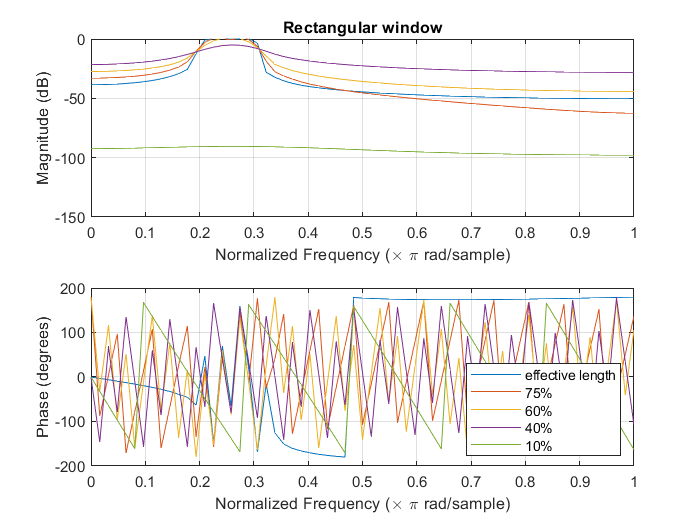

% Plot the frequency responses at different filter lengths
figure("Name", "Frequency response at different effective lengths")
f = linspace(0,1,length(H_el_rect)); % Frequency vector for plotting
subplot(2,1,1)
plot(f, 20*log10(abs(H_el_rect))), hold on;
plot(f, 20*log10(abs(H_75el_rect))), hold on;
plot(f, 20*log10(abs(H_60el_rect))), hold on;
plot(f, 20*log10(abs(H_40el_rect))), hold on;
plot(f, 20*log10(abs(H_10el_rect))), hold off
grid on
ylim([-150 0])
xlabel("Normalized Frequency (\times \pi rad/sample)")
ylabel("Magnitude (dB)")
title("Rectangular window")
subplot(2,1,2)
plot(f, rad2deg(angle(H_el_rect))), hold on;
plot(f, rad2deg(angle(H_75el_rect))), hold on;
plot(f, rad2deg(angle(H_60el_rect))), hold on;
plot(f, rad2deg(angle(H_40el_rect))), hold on;
plot(f, rad2deg(angle(H_10el_rect))), hold off
grid on
xlabel("Normalized Frequency (\times \pi rad/sample)")
ylabel("Phase (degrees)")
legend(["effective length", "75%", "60%", "40%", "10%"],"Location", "southeast");
saveas(gcf,"plots/eff_length_freq_resp_rect_window","png");

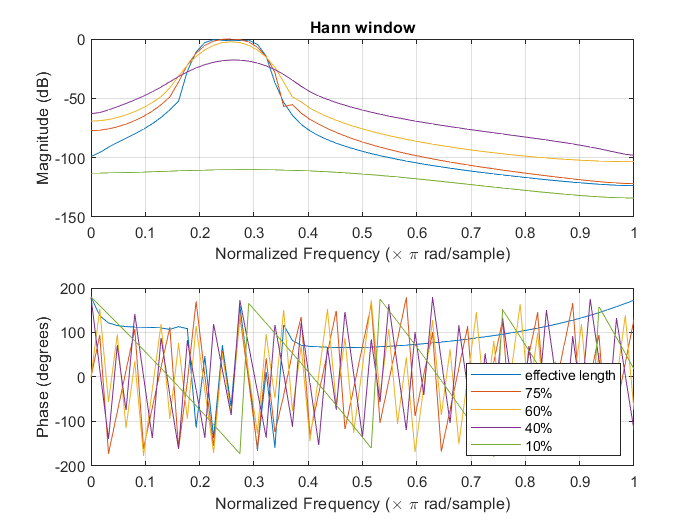

figure("Name", "Frequency response at different effective lengths using Hann window")
subplot(2,1,1)
plot(f, 20*log10(abs(H_el_hann))), hold on;
plot(f, 20*log10(abs(H_75el_hann))), hold on;
plot(f, 20*log10(abs(H_60el_hann))), hold on;
plot(f, 20*log10(abs(H_40el_hann))), hold on;
plot(f, 20*log10(abs(H_10el_hann))), hold off
grid on
xlabel("Normalized Frequency (\times \pi rad/sample)")
ylabel("Magnitude (dB)")
title("Hann window")
subplot(2,1,2)
plot(f, rad2deg(angle(H_el_hann))), hold on;
plot(f, rad2deg(angle(H_75el_hann))), hold on;
plot(f, rad2deg(angle(H_60el_hann))), hold on;
plot(f, rad2deg(angle(H_40el_hann))), hold on;
plot(f, rad2deg(angle(H_10el_hann))), hold off
grid on
xlabel("Normalized Frequency (\times \pi rad/sample)")
ylabel("Phase (degrees)")
legend(["effective length", "75%", "60%", "40%", "10%"],"Location", "southeast");
saveas(gcf,"plots/eff_length_freq_resp_hann_window","png");

### 1.2 Shorter and shorter

For an application you are to construct a FIR lowpass filter by the frequency domain equivalence, i.e. by sampling the frequency response of a perfect lowpass filter. You got a sheet of paper from you colleague that holds the specs: The filter passes all frequencies between 0 and 5 kHz with a gain af 0 dB. Just over the sampling frequency, there is this huge coffee stain, making it impossible to read, the same for the order of the desired filter. But you see from the sketch that the cutoff of the filter corresponds to one third on a normalized frequency axis, and you can see that the impulse response should be 601 samples long. 

- Which sampling rate should you use? 

- Construct the filter and plot the frequency and the impulse response

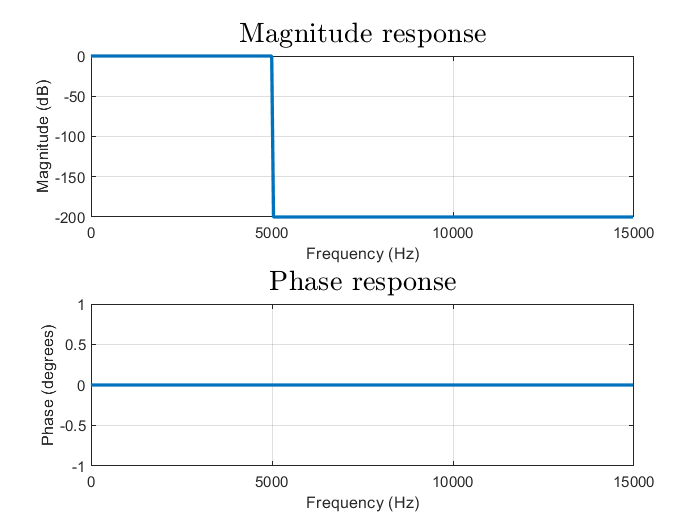

fs = 30e3;  % Sampling frequency
fn = fs/2;  % Nyquist frequency
L = 601;    % Length of impuæse response
T = L/fs; % Duration of impulse response
df = 1/T;
f = 0:df:fn; % Frequency vector
Y = [ones(1,ceil(length(f)/3)) 1e-10*ones(1,floor(2*length(f)/3))];
f = [-flip(f) f(2:end)];
Y = [flip(Y) Y(2:end)];  % Make Y two-sided centered around 0 Hz

% Frequency response of the idealized low-pass filter
figure("Name", "Frequency response")
subplot(2,1,1)
plot(f,20*log10(abs(Y)), "LineWidth", 2)
grid on
xlim([0 fn]) % Only plot positive frequencies
xlabel("Frequency (Hz)")
ylabel("Magnitude (dB)")
title("Magnitude response",'Interpreter',"latex",'FontSize', 17);
subplot(2,1,2);
plot(f,angle(Y)*180/pi, "LineWidth", 2);
grid on
xlim([0 fn])
xlabel("Frequency (Hz)")
ylabel("Phase (degrees)")
title("Phase response",'Interpreter',"latex",'FontSize', 17);
saveas(gcf, "plots/freq_resp_lowpass_fir", "pdf")

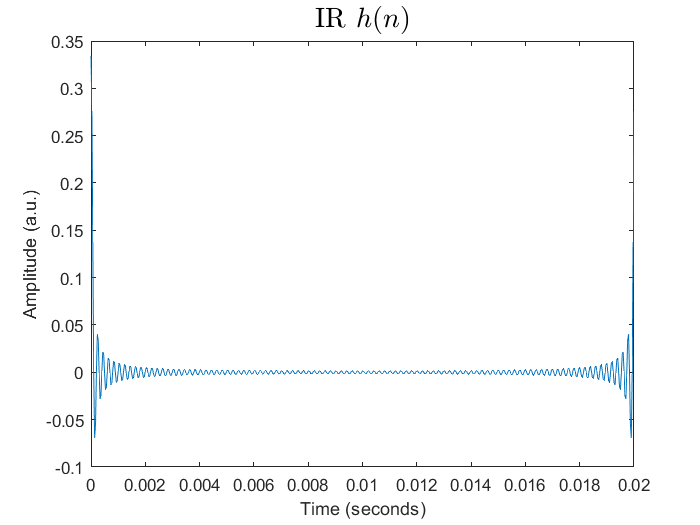

% Impulse response
h = ifft(ifftshift(Y));
t = 0:1/fs:T-1/fs;
figure("Name", "Impulse response 1")
plot(t,h)
xlabel("Time (seconds)")
ylabel("Amplitude (a.u.)")
title("IR $h(n)$",'Interpreter',"latex",'FontSize', 17);
saveas(gcf,"plots/impulse_resp_lowpass_fir", "pdf")

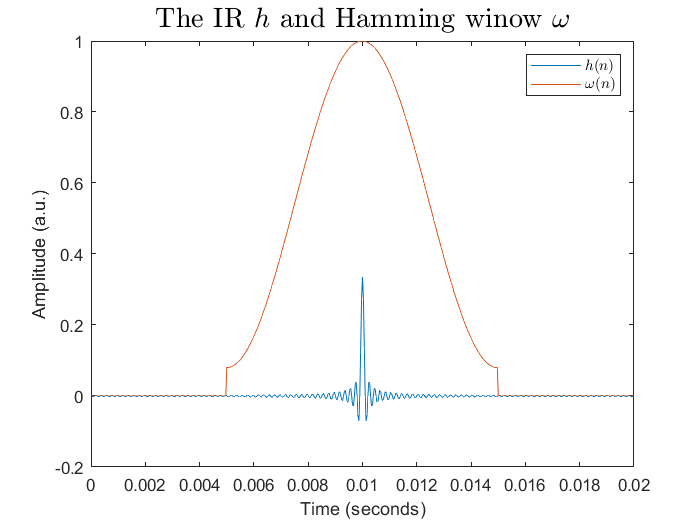

% Hamming window
w = [zeros(1,0.005*fs) hamming(0.01*fs)' zeros(1,0.005*fs+1)];
w_sig = w.*fftshift(h);

% Plot impulse response on top of Hamming window
figure("Name", "Impulse response and window function");
plot(t,fftshift(h)), hold on;
plot(t,w), hold off
xlabel("Time (seconds)")
ylabel("Amplitude (a.u.)")
title("The IR $h$ and Hamming winow $\omega$",'Interpreter',"latex",'FontSize', 17);
legend(["$h(n)$", "$\omega(n)$"], "Interpreter", "latex", "Location", "northeast");
saveas(gcf, "plots/hamming_window_lowpass_fir", "pdf")

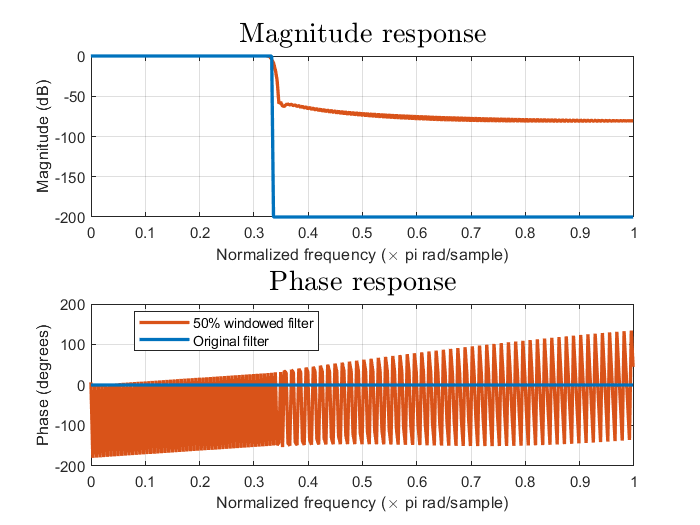

% Frequency spectrum
Y2 = fftshift(fft(w_sig));

% Frequency response
figure("Name", "Frequency response")
subplot(2,1,1)
plot(f/fn,20*log10(abs(Y2)), "LineWidth", 2, "Color", [0.8500, 0.3250, 0.0980]	), hold on;
plot(f/fn,20*log10(abs(Y)), "LineWidth", 2, "Color", [0, 0.4470, 0.7410]), hold off
grid on
xlim([0 1])
xlabel("Normalized frequency (\times pi rad/sample)")
ylabel("Magnitude (dB)")
title("Magnitude response",'Interpreter',"latex",'FontSize', 17);
subplot(2,1,2);
plot(f/fn,angle(Y2)*180/pi, "LineWidth", 2, "Color", [0.8500, 0.3250, 0.0980]), hold on;
plot(f/fn,angle(Y)*180/pi, "LineWidth", 2, "Color", [0, 0.4470, 0.7410]), hold off
grid on
xlim([0 1])
xlabel("Normalized frequency (\times pi rad/sample)")
ylabel("Phase (degrees)")
title("Phase response",'Interpreter',"latex",'FontSize', 17);
legend(["50% windowed filter", "Original filter"], "Location", "best")
saveas(gcf, "plots/freq_resp_window_lowpass_fir", "pdf")

## 2 An equalizer - without buttons

### 2.1 Bass and treble

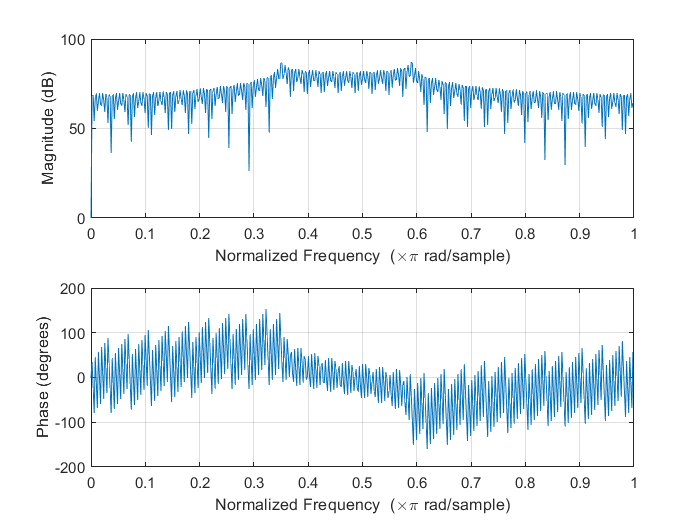

[b,a] = fir_bandpass_filter(...
    0.3636,...
    0.5979, ...
    82, ...
    559);

freqz(b,a)

% Pass scrambled_eggs_5s.wav sound through our filter
[y,fs] = audioread("sounds\scrambled_eggs_5s.wav");
y_filt = filter(b,a,y);

% Play the original and filtered sound (Watch the volume!)
soundsc(y,fs);
pause(5);
soundsc(y_filt,fs);

function [b,a] = fir_bandpass_filter(w_c_lwr,w_c_upr,G,L)
idx_lwr = fix(w_c_lwr*fix(L/2));
idx_upr = fix(w_c_upr*fix(L/2));
Y = ones(1,ceil(L/2));
for i = idx_lwr:idx_upr
    Y(i) = 10^(G/20);
end
Y = [flip(Y) Y(2:end)];
h = ifft(ifftshift(Y));
b = h;
a = [1];
end